% _________________problem 5.2_________________
L=[0 0 0 0 0;
    -1 2 -1 0 0;
    0 -1 2 -1 0;
    0 0 -1 2 -1;
    0 0 0 -1 1];
eig(L)

ans =     0.1206
    3.5321
    2.3473
    1.0000
         0


%_________________CONTINUOUS TIME ________________
tspan = [0 30];
gamma=5;
a = [zeros(5,5),eye(5);
        -L,-gamma*L];
disp(a);

     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     0
     1    -2     1     0     0     5   -10     5     0     0
     0     1    -2     1     0     0     5   -10     5     0
     0     0     1    -2     1     0     0     5   -10     5
     0     0     0     1    -1     0     0     0     5    -5



%b is the added bias to reach platooning
b = [zeros(9,1);-2];
disp(b);

     0
     0
     0
     0
     0
     0
     0
     0
     0
    -2



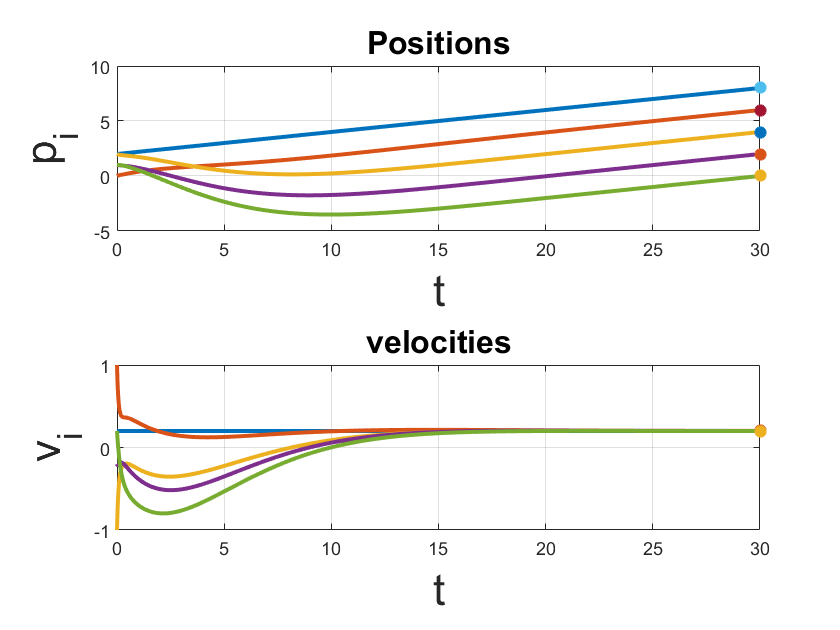

%b=zeros(10,1)
x0 = [2;0;2;1;1; 0.2; 1;-1;-0.2; 0.2];
options = odeset('RelTol',1e-5);
[t, x] = ode45(@(t,x) odefun(t,x,a,b), tspan, x0, options);

figure(1)
subplot(2,1,1)

plot(t,x(:,1:5),'linewidth',2)
hold on
plot(t(end,:),x(end,1:5),'*','linewidth',2);
xlabel('t', 'FontSize', 22);
ylabel('p_i', 'FontSize', 22);
title('Positions', 'FontSize', 16)
%legend('1','2','3','4', '5','final pos of 1','final pos of 2','final pos of 3','final pos of 4','final pos of 5','FontSize', 14)
grid on

subplot(2,1,2)

plot(t,x(:,6:10),'linewidth',2)
hold on
plot(t(end,:),x(end,6:10),'*','linewidth',2);
xlabel('t', 'FontSize', 22);
ylabel('v_i', 'FontSize', 22);
title('velocities', 'FontSize', 16)
%legend('1','2','3','4', '5','final vel of 1','final vel of 2','final vel of 3','final vel of 4','final vel of 5','FontSize', 14)
grid on

%_________________function definition__________________

function dxdt = odefun(t, x, a, b)
    dxdt = a*x + b;
end
